# This is Q3 of the assignment

t = -1:0.001:1;
t_temp = -2:0.001:2;
l = length(t);

x = u(t);

x1_t = t + 0.3*ones(l);
x1 = u(x1_t) - u(t);

x2_t_1 = t + 0.5*ones(l);
x2_t_2 = t - 0.7*ones(l);
x2 = u(x2_t_1) - u(x2_t_2);

y = conv(x1,x2)/1000;

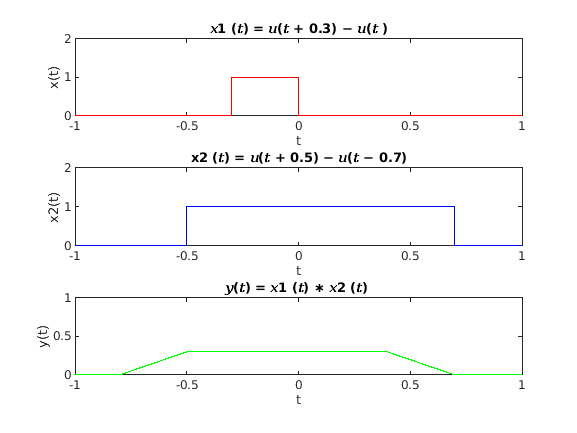

subplot(3,1,1); 
plot(t,x1,'r'); 
title('𝑥1 (𝑡) = 𝑢(𝑡 + 0.3) − 𝑢(𝑡 )');
ylabel('x(t)');
xlabel('t'); 
axis([-1 1 0 2]);

subplot(3,1,2);
plot(t,x2,'b');
title('x2 (𝑡) = 𝑢(𝑡 + 0.5) − 𝑢(𝑡 − 0.7)');
ylabel('x2(t)');
xlabel('t');
axis([-1 1 0 2]);

subplot(3,1,3);
plot(t_temp,y,'g');
title('𝑦(𝑡) = 𝑥1 (𝑡) ∗ 𝑥2 (𝑡) ');
ylabel('y(t)');
xlabel('t');
axis([-1 1 0 1]);